close all;
clear;
clc;
% addpath('Twin Rotor system')  

g = 9.81; %gravity
m = 1.535; %mass of drone
l=0.5; %Length planar twin rotor
Izz=0.255;

% Desired Fixed values
% theta_d=1.0;
x_pos_d=50.0;
y_pos_d=36.0;


x_pos=0.0;
y_pos=0.0;
theta=0;


% Time period of controller(50 ms)
dt = 0.01;

% Total simulation time
t_total = 50;

tspan = 0:dt:t_total; % Full time range

y0 = zeros(6, 1); % Initial state
u = [0.0;0.0]; % Initial control input

y_all = []; % To store all states
t_all = []; % To store all time
thrust_all=[];

current_state = y0; % Start with the initial state
del_T=0.0;
T_norm=0.0;
T_x=0.0;
T_y=0.0;


% USING PD CONTROLLER

%PD gains for controller

kp_theta=8.3;
kd_theta=4.0;
kp_y=0.5;
kd_y=0.6;
kp_x=0.5;
kd_x=0.6;

% Declaring Temp variables;
error_prev_theta=0;
error_prev_y=0.0;
error_prev_x=0.0;


for i = 1:length(tspan)-1

    t_current = [tspan(i), tspan(i+1)];
    
    [T_x,error_prev_x]=pd_control(x_pos,x_pos_d,error_prev_x,kp_x,kd_x,dt);
    [T_y,error_prev_y]=pd_control(y_pos,y_pos_d,error_prev_y,kp_y,kd_y,dt);
    T_x=T_x+m*g;

    theta_d=atan(T_y/T_x);
    [del_T,error_prev_theta]=pd_control(theta,theta_d,error_prev_theta,kp_theta,kd_theta,dt);
    
    T_norm=sqrt(T_x^2+T_y^2);
    
    u(1)=T_norm/2+del_T;
    u(2)=T_norm/2-del_T;
    u(1) = max(u(1), 0);
    u(2) = max(u(2), 0);
    u(1) = min(u(1), 50);
    u(2) = min(u(2), 50);
    % Solve ODE for this time step
    
    [t, fx] = ode45(@(t, fx) twinRotordynamics(t, fx,m,g,l,Izz, u), t_current, current_state);
    
    % Store all the results
    y_all = [y_all; fx(1:end-1, :)]; % Exclude the last point to avoid duplication
    t_all = [t_all; t(1:end-1)];
    thrust_all = [thrust_all; u(1), u(2)];

    % Update the current state of the variables
    current_state = fx(end, :)';
    theta=current_state(5);
    y_pos=current_state(2);
    x_pos=current_state(1);


end

% Add the final point
y_all = [y_all; current_state'];
t_all = [t_all; tspan(end)];


% USING PID CONTROLLER


kp_theta=8.3;
ki_theta=0.0001;
kd_theta=4.0;

kp_y=0.5;
ki_y=0.001;
kd_y=0.6;

kp_x=0.5;
ki_x=0.001;
kd_x=0.6;


% Declaring Temp variables;
error_prev_theta=0;
error_prev_y=0.0;
error_prev_x=0.0;

error_in_theta=0.0;
error_in_y=0.0;
error_in_x=0.0;


for i = 1:length(tspan)-1

    t_current = [tspan(i), tspan(i+1)];
    
    [T_x,error_prev_x,error_in_x]=pid_control(x_pos,x_pos_d,error_prev_x,error_in_x,kp_x,ki_x,kd_x,dt);
    [T_y,error_prev_y,error_in_y]=pid_control(y_pos,y_pos_d,error_prev_y,error_in_y,kp_y,ki_y,kd_y,dt);
    % T_x=T_x+m*g;

    theta_d=atan(T_y/T_x);
    [del_T,error_prev_theta,error_in_theta]=pid_control(theta,theta_d,error_prev_theta,error_in_theta,kp_theta,ki_theta,kd_theta,dt);
    
    T_norm=sqrt(T_x^2+T_y^2);
    
    u(1)=T_norm/2+del_T;
    u(2)=T_norm/2-del_T;
    u(1) = max(u(1), 0);
    u(2) = max(u(2), 0);
    u(1) = min(u(1), 50);
    u(2) = min(u(2), 50);
    % Solve ODE for this time step
    
    [t, fx] = ode45(@(t, fx) twinRotordynamics(t, fx,m,g,l,Izz, u), t_current, current_state);
    
    % Store all the results
    y_all = [y_all; fx(1:end-1, :)]; % Exclude the last point to avoid duplication
    t_all = [t_all; t(1:end-1)];
    thrust_all = [thrust_all; u(1), u(2)];

    % Update the current state of the variables
    current_state = fx(end, :)';
    theta=current_state(5);
    y_pos=current_state(2);
    x_pos=current_state(1);


end

% Add the final point
y_all = [y_all; current_state'];
t_all = [t_all; tspan(end)];
theta=current_state(5)
y_pos=current_state(2)
x_pos=current_state(1)



theta=current_state(5)

theta = 1.5528e-07

y_pos=current_state(2)

y_pos = 36.0000

x_pos=current_state(1)

x_pos = 50.0000

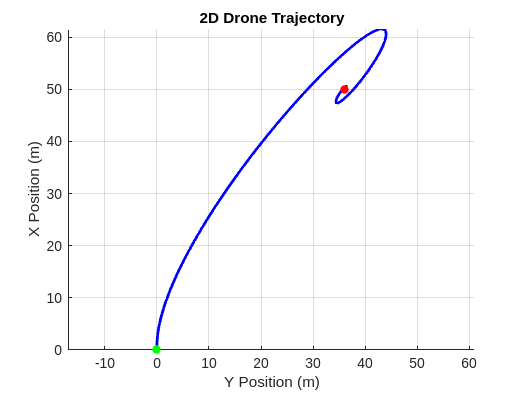


figure;
hold on;
axis equal;
grid on;
xlabel('Y Position (m)');
ylabel('X Position (m)');
title('2D Drone Trajectory');

% Plot trajectory
plot(y_all(:, 2), y_all(:, 1), 'b-', 'LineWidth', 2); % x vs y trajectory
scatter(y_all(1, 2), y_all(1, 1), 'g', 'filled'); % Start point
scatter(y_all(end, 2), y_all(end, 1), 'r', 'filled'); % End point

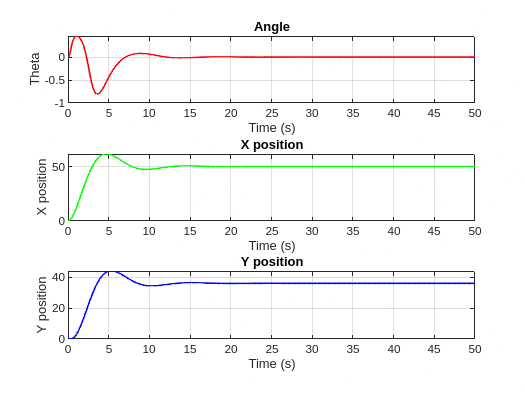


figure;
subplot(3, 1, 1);
plot(t_all, y_all(:, 5), 'r', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('Theta');
title('Angle');



subplot(3, 1, 2);
plot(t_all, y_all(:, 1), 'g', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('X position');
title('X position');


subplot(3, 1, 3);
plot(t_all, y_all(:, 2), 'b', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('Y position');
title('Y position');